x = [0.83, 0.85, 0.87, 0.89];
y = [f(0.83), f(0.85), f(0.87), f(0.89)];
y

y =     2.2933    2.3396    2.3869    2.4351


value_at = 0.84;

n = length(x);
Divided_differences = zeros(n,n);

Divided_differences(:,1) = y;

for j = 2:n
    for i=j:n
        Divided_differences(i,j) = (Divided_differences(i,j-1) - Divided_differences(i-1,j-1))/(x(i)-x(i-j+1));
    end
end
Divided_differences

Divided_differences =     2.2933         0         0         0
    2.3396    2.3164         0         0
    2.3869    2.3632    1.1699         0
    2.4351    2.4109    1.1935    0.3939



c = Divided_differences(n,n);

for k=n-1:-1:1
    c = conv(c,poly(x(k)));
    m = length(c);
    c(m) = c(m) + Divided_differences(k,k);
end

coefficients = c

coefficients =     0.3939    0.1655    1.2046    0.9543


A = polyval(c,value_at);
fprintf('Interpolated value of the function at %0.15g is %.4f.\n',value_at,A);

Interpolated value of the function at 0.84 is 2.3164.


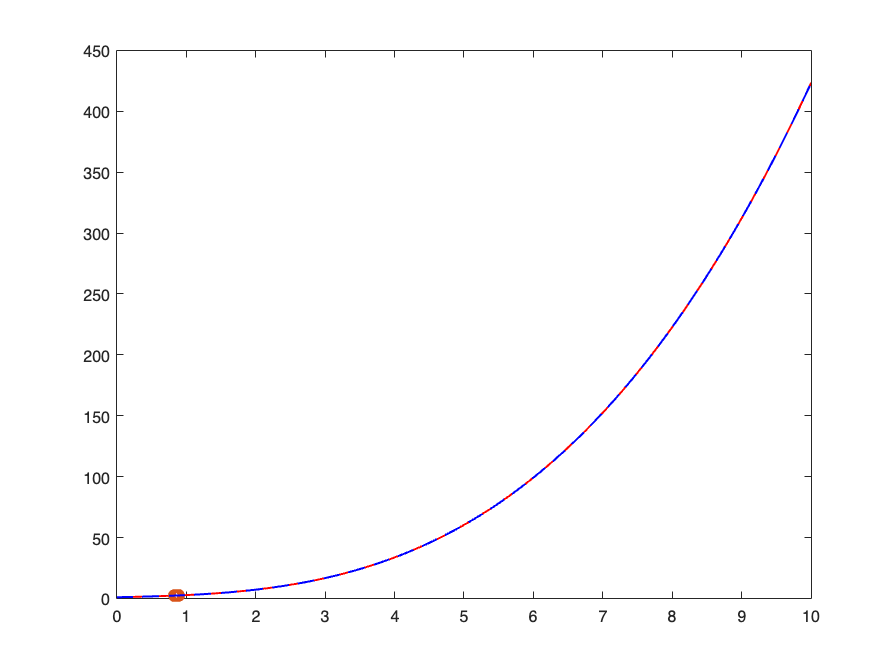


X = linspace(0,10,100);
Y = polyval(c,X);
Y2 = exp(X);            % original value


plot(X,Y,'r',LineStyle='-',LineWidth=1.2);
hold on;
plot(x,y,'o',LineWidth=2);
plot(X,Y,'b',LineStyle='--',LineWidth=1.25);

hold off;

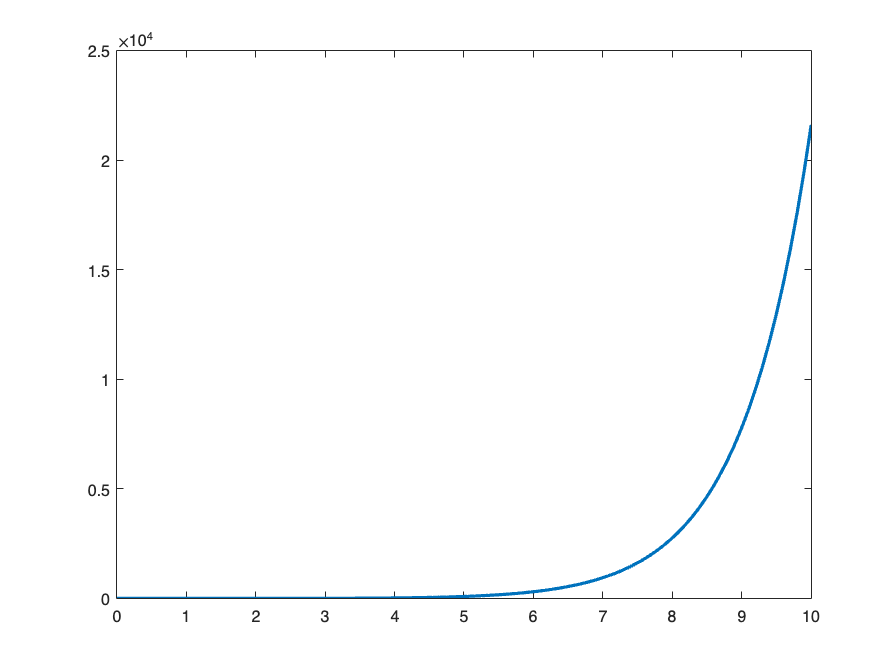


difference = Y2-Y;
plot(X,difference,LineWidth=2);

function ret_val = f(passed_value)
    ret_val = exp(passed_value);
end